s = tf('s');
G = 20 / (s*(s+2)*(s+5));
G


G =
 
          20
  ------------------
  s^3 + 7 s^2 + 10 s
 
Continuous-time transfer function.


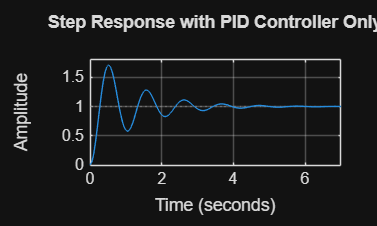

Kp = 10;
Ki = 8;
Kd = 2;

C_pid = pid(Kp, Ki, Kd);

% Closed-loop system
T_pid = feedback(C_pid * G, 1);

% Step response
figure;
step(T_pid);
grid on;
title('Step Response with PID Controller Only');


% Performance metrics
info_pid = stepinfo(T_pid);
info_pid

info_pid = struct with fields:
         RiseTime: 0.1838
    TransientTime: 4.3297
     SettlingTime: 4.3297
      SettlingMin: 0.5758
      SettlingMax: 1.7133
        Overshoot: 71.3322
       Undershoot: 0
             Peak: 1.7133
         PeakTime: 0.5200


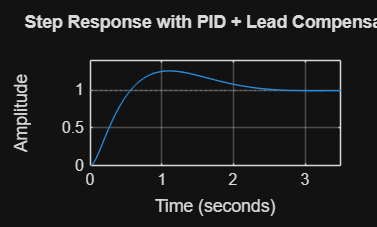

%% Lead Compensator Design

z = 3;
p = 15;
K = 1;

C_lead = K * (s + z) / (s + p);

% Combined controller
C_total = C_pid * C_lead;

% Closed-loop system with lead
T_lead = feedback(C_total * G, 1);

% Step response
figure;
step(T_lead);
grid on;
title('Step Response with PID + Lead Compensator');


% Performance metrics
info_lead = stepinfo(T_lead);
info_lead

info_lead = struct with fields:
         RiseTime: 0.4014
    TransientTime: 2.4149
     SettlingTime: 2.4149
      SettlingMin: 0.9068
      SettlingMax: 1.2560
        Overshoot: 25.5989
       Undershoot: 0
             Peak: 1.2560
         PeakTime: 1.1000


The lead compensator adds **phase lead near crossover frequency**

This increases **phase margin**

Dominant closed-loop poles move **further left**

Result: faster rise time and settling time

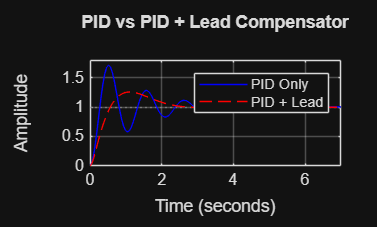

%% Performance Comparison Plot

figure;
step(T_pid, 'b', T_lead, 'r--');
grid on;
legend('PID Only', 'PID + Lead');
title('PID vs PID + Lead Compensator');

%% Performance Comparison Table

Performance = table( ...
    [info_pid.RiseTime; info_lead.RiseTime], ...
    [info_pid.SettlingTime; info_lead.SettlingTime], ...
    [info_pid.Overshoot; info_lead.Overshoot], ...
    'VariableNames', {'RiseTime', 'SettlingTime', 'Overshoot'}, ...
    'RowNames', {'PID Only', 'PID + Lead'} ...
);

Performance

Performance = 2×3 table
                  RiseTime    SettlingTime    Overshoot
                  ________    ____________    _________

    PID Only      0.18378        4.3297        71.332  
    PID + Lead    0.40141        2.4149        25.599  


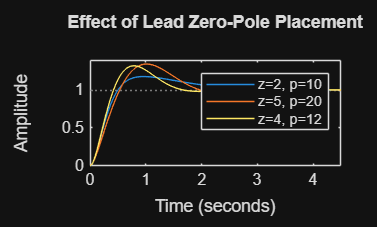

%% Parameter Experimentation

z_vals = [2, 5, 4];
p_vals = [10, 20, 12];

figure;
hold on;
grid on;

for i = 1:length(z_vals)
    C_lead_test = (s + z_vals(i)) / (s + p_vals(i));
    T_test = feedback(C_pid * C_lead_test * G, 1);
    step(T_test);
end

legend('z=2, p=10', 'z=5, p=20', 'z=4, p=12');
title('Effect of Lead Zero-Pole Placement');

Larger pole-zero separation → stronger phase lead

Too aggressive separation increases overshoot

Moderate separation gives best speed-stability trade-off

s = tf('s');

% Given plant
G = 50 / ((s+1)*(s+3)*(s+8));

% Display plant
G


G =
 
             50
  ------------------------
  s^3 + 12 s^2 + 35 s + 24
 
Continuous-time transfer function.


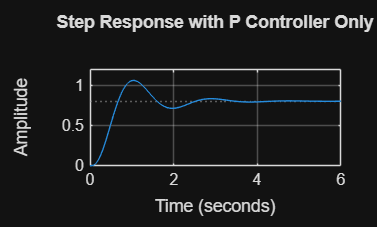

%% Proportional Controller Analysis

Kp = 2;
C_p = Kp;

% Closed-loop system
T_p = feedback(C_p * G, 1);

% Step response
figure;
step(T_p);
grid on;
title('Step Response with P Controller Only');


% Final value
[y_p, t_p] = step(T_p);
y_final_p = y_p(end);

% Steady-state error
ess_p = abs(1 - y_final_p);

ess_p

ess_p = 0.1920

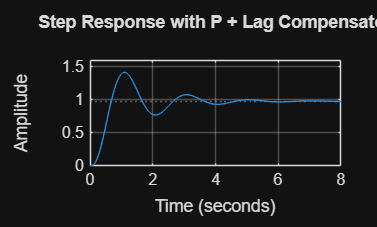

%% Lag Compensator Design

z = 1;
p = 0.1;
Kc = 1;

C_lag = Kc * (s + z) / (s + p);

% Combined controller
C_total = C_p * C_lag;

% Closed-loop system
T_lag = feedback(C_total * G, 1);

% Step response
figure;
step(T_lag);
grid on;
title('Step Response with P + Lag Compensator');

%% Steady-State Error Comparison

% Final values
[y_lag, t_lag] = step(T_lag);
y_final_lag = y_lag(end);

% Steady-state errors
ess_lag = abs(1 - y_final_lag);

% Error reduction percentage
error_reduction = ((ess_p - ess_lag) / ess_p) * 100;

% Settling times
info_p = stepinfo(T_p);
info_lag = stepinfo(T_lag);

% Table
Comparison = table( ...
    [ess_p; ess_lag], ...
    [info_p.SettlingTime; info_lag.SettlingTime], ...
    'VariableNames', {'SteadyStateError', 'SettlingTime'}, ...
    'RowNames', {'P Only', 'P + Lag'} ...
);

Comparison

Comparison = 2×2 table
               SteadyStateError    SettlingTime
               ________________    ____________

    P Only          0.19202           3.2198   
    P + Lag        0.025389           5.2126   


error_reduction

error_reduction = 86.7778

Lag compensator increases **low-frequency gain**

Steady-state error depends on system gain at s→0s \to 0s→0

Pole closer to origin increases DC gain

Transient response is mostly unaffected at high frequencies

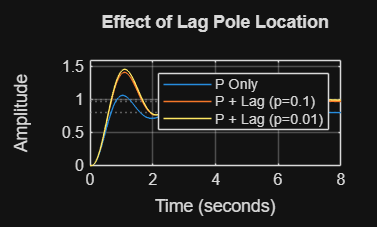

%% Trade-off Analysis with Smaller Pole

p_new = 0.01;
C_lag_new = (s + z) / (s + p_new);

T_lag_new = feedback(C_p * C_lag_new * G, 1);

figure;
step(T_p, T_lag, T_lag_new);
grid on;
legend('P Only', 'P + Lag (p=0.1)', 'P + Lag (p=0.01)');
title('Effect of Lag Pole Location');

Smaller pole → higher DC gain

Steady-state error further reduced

Settling time increases noticeably

Response becomes slower and more sluggish

dt = 0.01;
t = 0:dt:30;
N = length(t);

% Plant parameters
a = 0.5;

% Reference signal
r = ones(1, N);   % r(t) = 1 (constant speed)

% Disturbance (known)
d = zeros(1, N);
d(t >= 5) = 0.3;  % disturbance applied at t = 5s

%% Feedback-Only PI Control

Kp = 2;
Ki = 1;

y_fb = zeros(1, N);     % output
u_fb = zeros(1, N);     % control input
e = zeros(1, N);        % error
ei = 0;                 % integral of error

for k = 2:N
    % Error
    e(k) = r(k) - y_fb(k-1);
    ei = ei + e(k)*dt;

    % PI control
    u_fb(k) = Kp*e(k) + Ki*ei;

    % Plant dynamics (Euler discretization)
    y_fb(k) = y_fb(k-1) + dt*(-a*y_fb(k-1) + u_fb(k) - d(k));
end

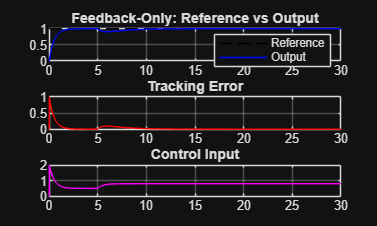

%% Feedback-Only Response

figure;
subplot(3,1,1)
plot(t, r, 'k--', t, y_fb, 'b')
grid on;
title('Feedback-Only: Reference vs Output')
legend('Reference', 'Output')

subplot(3,1,2)
plot(t, e, 'r')
grid on;
title('Tracking Error')

subplot(3,1,3)
plot(t, u_fb, 'm')
grid on;
title('Control Input')

%% Feedforward + Feedback Control

Kff = 0.5;

y_ff = zeros(1, N);
u_fb2 = zeros(1, N);
u_ff = zeros(1, N);
u_total = zeros(1, N);

e2 = zeros(1, N);
ei2 = 0;

for k = 2:N
    % Feedback error
    e2(k) = r(k) - y_ff(k-1);
    ei2 = ei2 + e2(k)*dt;

    % Feedback control
    u_fb2(k) = Kp*e2(k) + Ki*ei2;

    % Feedforward compensation
    u_ff(k) = Kff * d(k);

    % Total control
    u_total(k) = u_fb2(k) + u_ff(k);

    % Plant
    y_ff(k) = y_ff(k-1) + dt*(-a*y_ff(k-1) + u_total(k) - d(k));
end

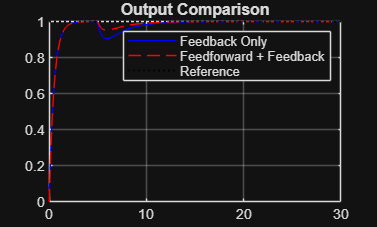

%% Comparison Plots

figure;
plot(t, y_fb, 'b', t, y_ff, 'r--', t, r, 'k:')
grid on;
legend('Feedback Only', 'Feedforward + Feedback', 'Reference')
title('Output Comparison')

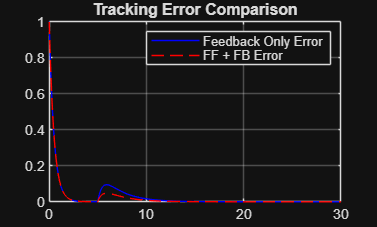

%% Error Comparison

figure;
plot(t, abs(r - y_fb), 'b', t, abs(r - y_ff), 'r--')
grid on;
legend('Feedback Only Error', 'FF + FB Error')
title('Tracking Error Comparison')

%% Performance Metrics

% Maximum error after disturbance
idx = find(t >= 5, 1);

max_err_fb = max(abs(r(idx:end) - y_fb(idx:end)));
max_err_ff = max(abs(r(idx:end) - y_ff(idx:end)));

% Steady-state error
ess_fb = abs(r(end) - y_fb(end));
ess_ff = abs(r(end) - y_ff(end));

Performance = table( ...
    [max_err_fb; max_err_ff], ...
    [ess_fb; ess_ff], ...
    'VariableNames', {'MaxErrorAfterDisturbance', 'SteadyStateError'}, ...
    'RowNames', {'Feedback Only', 'Feedforward + Feedback'} ...
);

Performance

Performance = 2×2 table
                              MaxErrorAfterDisturbance    SteadyStateError
                              ________________________    ________________

    Feedback Only                      0.09478                7.731e-07   
    Feedforward + Feedback            0.047451               3.8691e-07   


Feedback reacts **after error occurs**

Feedforward predicts disturbance and compensates **before it affects output**

Combined control provides:

Feedforward → disturbance rejection

Feedback → robustness and correction

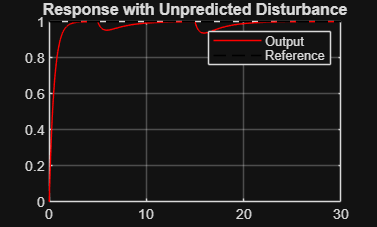

d2 = d;
d2(t >= 15) = d2(t >= 15) + 0.2;  % unpredicted disturbance

y_un = zeros(1, N);
ei3 = 0;

for k = 2:N
    e3 = r(k) - y_un(k-1);
    ei3 = ei3 + e3*dt;

    u_fb3 = Kp*e3 + Ki*ei3;
    u_ff3 = Kff * d(k);   % only compensates known disturbance

    u_total3 = u_fb3 + u_ff3;

    y_un(k) = y_un(k-1) + dt*(-a*y_un(k-1) + u_total3 - d2(k));
end
%% Unpredicted Disturbance Response

figure;
plot(t, y_un, 'r', t, r, 'k--')
grid on;
title('Response with Unpredicted Disturbance')
legend('Output', 'Reference')

Feedforward fails when disturbance is unknown

Feedback compensates unknown disturbances

Feedforward improves performance **only when disturbance model is accurate**

Best performance achieved using **both together**

s = tf('s');

% Individual transfer functions
G11 = 1/(s+1);        % u1 -> h1 (main)
G12 = 0.5/(s+1);      % u2 -> h1 (coupling)
G21 = 0.3/(s+1.5);    % u1 -> h2 (coupling)
G22 = 1/(s+1.5);      % u2 -> h2 (main)

% MIMO plant matrix
G = [G11 G12;
     G21 G22];

G


G =
 
  From input 1 to output...
         1
   1:  -----
       s + 1
 
         0.3
   2:  -------
       s + 1.5
 
  From input 2 to output...
        0.5
   1:  -----
       s + 1
 
          1
   2:  -------
       s + 1.5
 
Continuous-time transfer function.


Each input affects **both outputs**, confirming this is a **coupled MIMO system**

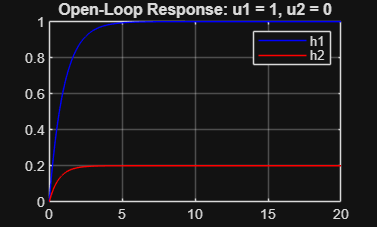

%% Open-Loop Response: u1 = 1, u2 = 0

t = 0:0.01:20;

u = [ones(size(t)); zeros(size(t))];   % [u1; u2]

y = lsim(G, u', t);

figure;
plot(t, y(:,1), 'b', t, y(:,2), 'r')
grid on;
legend('h1', 'h2')
title('Open-Loop Response: u1 = 1, u2 = 0')

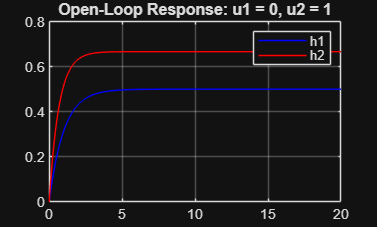

%% Open-Loop Response: u1 = 0, u2 = 1

u = [zeros(size(t)); ones(size(t))];

y = lsim(G, u', t);

figure;
plot(t, y(:,1), 'b', t, y(:,2), 'r')
grid on;
legend('h1', 'h2')
title('Open-Loop Response: u1 = 0, u2 = 1')

%% Decentralized PI Controllers

Kp1 = 1.5; Ki1 = 0.8;
Kp2 = 1.2; Ki2 = 0.6;

dt = 0.01;
t = 0:dt:30;
N = length(t);

% References
r1 = ones(1,N);
r2 = ones(1,N);

% States
h1 = zeros(1,N);
h2 = zeros(1,N);

u1 = zeros(1,N);
u2 = zeros(1,N);

e1_int = 0;
e2_int = 0;

%% Closed-Loop Simulation (Euler Approximation)

for k = 2:N
    % Errors
    e1 = r1(k) - h1(k-1);
    e2 = r2(k) - h2(k-1);

    % Integrals
    e1_int = e1_int + e1*dt;
    e2_int = e2_int + e2*dt;

    % PI controllers
    u1(k) = Kp1*e1 + Ki1*e1_int;
    u2(k) = Kp2*e2 + Ki2*e2_int;

    % Plant dynamics
    dh1 = -h1(k-1) + u1(k) + 0.5*u2(k);
    dh2 = -1.5*h2(k-1) + 0.3*u1(k) + u2(k);

    h1(k) = h1(k-1) + dt*dh1;
    h2(k) = h2(k-1) + dt*dh2;
end

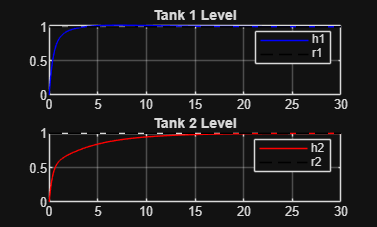

%% Closed-Loop Outputs

figure;
subplot(2,1,1)
plot(t, h1, 'b', t, r1, 'k--')
grid on;
title('Tank 1 Level')
legend('h1', 'r1')

subplot(2,1,2)
plot(t, h2, 'r', t, r2, 'k--')
grid on;
title('Tank 2 Level')
legend('h2', 'r2')

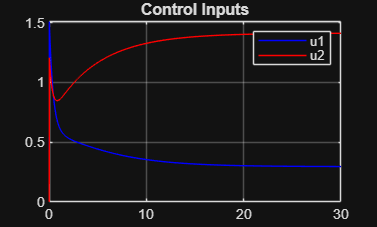

%% Control Inputs

figure;
plot(t, u1, 'b', t, u2, 'r')
grid on;
legend('u1', 'u2')
title('Control Inputs')

%% Performance Metrics

info_h1 = stepinfo(h1, t);
info_h2 = stepinfo(h2, t);

Results = table( ...
    [info_h1.SettlingTime; info_h2.SettlingTime], ...
    [h1(end); h2(end)], ...
    'VariableNames', {'SettlingTime', 'FinalValue'}, ...
    'RowNames', {'Tank 1', 'Tank 2'} ...
);

Results

Results = 2×2 table
              SettlingTime    FinalValue
              ____________    __________

    Tank 1       9.1209         1.0004  
    Tank 2       14.352        0.99922  


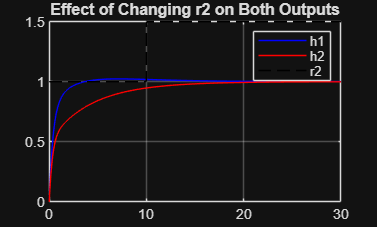

%% Sequential Setpoint Changes
r2(t >= 10) = 1.5;

figure;
plot(t, h1, 'b', t, h2, 'r', t, r2, 'k--')
grid on;
legend('h1', 'h2', 'r2')
title('Effect of Changing r2 on Both Outputs')

Inputs are **not independent**

Controllers interact through plant dynamics

Tuning one loop affects others

Decentralized control is limited

Advanced strategies (decoupling, LQR, MPC) are often required